## **Grado en Criminalística: Ciencias y Tecnologías Forenses **

# **Procesado de Imágenes para Análisis Forense**

Miguel Ángel García Garrido

Departmento de Electrónica. Universidad de Alcalá.

# Tema 6. Seguimiento de objetos múltiples basado en el movimiento

#  (Multiple Object Tracking)

**Nombre de los miembros del grupo**

- Miembro 1: Diego Pena

- Miembro 2: Isaac Marval

Al igual que en la práctica `"Seguimiento de un objeto en un vídeo`" se va a hacer uso de la técnica* 'Background Subtraction' *usando el modelo de mezcla de gaussianas (*GMM*), que en Matlab lo implementa el objeto `vision.ForegroundDetector`, aunque en este caso los parámetros de configuración ya están ajustados, aunque para mejorar la imagen del primer plano se puede hacer uso de los llamados [operadores morfológicos](https://es.mathworks.com/help/images/morphological-dilation-and-erosion.html)  para obtener mejores 'blobs'.

Después se obtendrá el centroide de todos los* 'blobs'* detectados mediante el análisis de regiones conectadas. Para ello se va a usar el objeto `vision.BlobAnalysis`, cuyo parámetro de configuración es:

-     `MinimumBlobArea`: área mínima en píxeles de un objeto para ser considerado una detección.

Una vez ajustados los parámetros para realizar una buena detección hay que realizar el ajuste de los parámetros para realizar el seguimientos de los objetos detectados, que son:

- `ageThreshold`: mínimo número de veces que se debe detectar un objeto para ser considerado un track.

- `visibilityThreshold`: el ratio mínimo que el track debe haber sido visible frente a su edad `(totalVisibleCounts/ages)`. si se supera este umbral y la edad es menor que `ageThreshold` el track se elimina.

- `invisibleForTooLong`: máximo número de veces que un track no se detecta (es invisible), si se supera este umbral el track se elimina.

- `costOfNonAssignment``:`coste de no asignar una detección a un track. Si es demasiado bajo, aumenta la probabilidad de crear nuevos tracks, mientras que si es demasiado alto, puede dar lugar a un único track que corresponda a una serie de objetos en movimiento separados.

- `MotionModel`: modelo de movimiento para el filtro de Kalman.

**Se pide:**

- Utilice el vídeo `'visiontraffic.avi'``.`

- Ajuste el valor `MinimumBlobArea` y aplique operaciones morfológicas, si lo considera necesario, hasta que obtenga buenas detecciones.  

- De valores a los parámetros de configuración del Tracking atendiendo a la definición de cada uno (`ageThreshold, visibilityThreshold`...). Ejecute el  código que muestra los resultados. **Importante**. Debe evitar que los tracks se "partan" si no hay oclusiones y que no haya saltos muy grande en las trayectorias.

- Repetir el proceso para el vídeo `'atrium.mp4'`. 

- Cambie el detector de '`Background Subtraction`' por el detector de objetos [`YOLO v4`](https://es.mathworks.com/help/vision/ref/yolov4objectdetector.html). Utilice el ejemplo  `T6_02_YOLO_v4_detections.mlx` para conocer cómo funciona. **NOTA**. Tenga en cuenta que el detector de YOLO no devuelve los centroides que se utilizan para actualizar el estado de los filtros de Kalman. 

`Nota``:`  Si lo desea puede visualizar individualmente los track utilizando la función `plotTrackID(frame, trackssum, ID) `indicando en ID del track. 

close all;
clear all; 
clc; 
addpath(genpath(pwd));

% nombre del vídeo que se va a utilizar
videofilename = 'visiontraffic.avi'; % 'atrium.mp4';


 % PARÁMETROS DE CONFIGURACIÓN PARA DETECCIÓN
 
    % área mínima para ser considerada una detección
    MinimumBlobArea = [750]; % <=== RELLENAR AQUI !!! 
    
 % PARÁMETROS DE CONFIGURACIÓN DEL TRACKING
    
    % coste de no asignar una detección a un track
    % depende del rango de valores devueltos por el método de la distancia de vision.KalmanFilter. 
    % Este valor debe ser ajustado experimentalmente. 
    % Si es demasiado bajo (~1), aumenta la probabilidad de crear un nuevo track
    % Si es demasiado alto (~100), puede dar lugar a un único track que corresponda a una serie de objetos en movimiento separados. 
    costOfNonAssignment = [20]; % <=== RELLENAR AQUI !!!
 
    % Un track se elimina si:
 
     % a) Es invisible durante un número consecutivo de frames (consecutiveInvisibleCount >= invisibleForTooLong)
     invisibleForTooLong = [20]; % <=== RELLENAR AQUI !!!
     
     % b) No cumple el ratio mínimo que el track debe haber sido visible frente a
     % su edad y su edad es menor de un cierto umbral (ageThreshold)
     % (totalVisibleCounts/ages) < visibilityThreshold && age < ageThreshold
     visibilityThreshold = [ 0.6]; % <=== RELLENAR AQUI !!!
     ageThreshold = [8]; % <=== RELLENAR AQUI !!!

 % PARÁMETRO DE CONFIGURACIÓN DEL FILTRO DE KALMAN
     
     % Modelo de movimiento del filtro de Kalman ('ConstantVelocity' o 'ConstantAcceleration')
     MotionModel = ['ConstantVelocity']; % <=== RELLENAR AQUI !!!


  % PARÁMETRO PARA VISUALIZACIÓN
  
    display.speed = 0.0; % indica el retardo (pausa) en frames para mejorar la visualización
    display.ageThreshold = ageThreshold; % visualiza los que cumplan age > ageThreshold
    display.marker = 'o';
    display.video_mode = 1;

    display.colors = [0.00 0.45 0.75;
         0.85 0.35 0.10;
         0.95 0.90 0.15;
         0.50 0.20 0.55;
         0.45 0.65 0.20;
         0.30 0.75 0.95;
         0.65 0.075 0.20;
         0.90 0.00 0.45;
         0.35 0.95 0.30;
         0.00 0.25 0.95];

obj = setupSystemObjects(videofilename, MinimumBlobArea);

% Crea una matriz vacía de tracks
[tracks trackssum]= initializeTracks();

% ID del frame
frameId = 1;

% ID del próximo track
nextId = 1;


% Detecta los objetos en movimiento y los rastrea a través de los frames del vídeo.
while hasFrame(obj.reader)
    
    frame = readFrame(obj.reader);
    
    % Detector Background Subtraction
    mask = obj.detector(frame);

    % OPCIONAL aplicar operaciones morfológicas

    % Realiza un análisis de blobs para encontrar los componentes conectados.
    [detections.area, detections.centroids, detections.bboxes] = obj.blobAnalyser(mask);
  
    % --- PREDICCIONES ---
        tracks = predictNewLocationsOfTracks(tracks);

    % --- ASIGNACIÓN ---
        [assignments, unassignedTracks, unassignedDetections] = detectionToTrackAssignment(tracks, detections.centroids, costOfNonAssignment);

    % --- ACTUALIZA TRACKS ASIGNADOS (CORRECCION) ---
        [tracks trackssum] = updateAssignedTracks(tracks, trackssum, assignments, detections);
    
    % --- ACTUALIZA TRACKS NO ASIGNADOS ---
        [tracks trackssum] = updateUnassignedTracks(tracks, trackssum, unassignedTracks);
    
    % --- BORRA TRACKS ---
        tracks = deleteLostTracks(tracks, invisibleForTooLong, ageThreshold, visibilityThreshold);
    
    % --- CREA NUEVOS TRACKS ---
        [tracks trackssum nextId] = createNewTracks(tracks, trackssum, detections, unassignedDetections, MotionModel, nextId, frameId);
    
    % --- MOSTRAR RESULTADOS ---
      displayTrackingResults(obj, frame, mask, tracks, trackssum, display);
       
    frameId = frameId + 1;

end

% Cierra la ventana que se usó para mostrar los frames del vídeo.
uiscopes.close('All'); 


## RESULTADOS

% Muestra una tabla con TODOS los datos de los Tracks
close all
display.ageThreshold = 0;
display.marker = 'o';
display.video_mode = 0;

% Muestra una tabla con TODOS los datos de los Tracks
T = infoTracks(trackssum, invisibleForTooLong, -1, display);

T = 6×6 table
    track_IDs    frame_i    ages    totalVisibleCounts    consecutiveInvisibleCount    visibility
    _________    _______    ____    __________________    _________________________    __________

        1           99      100             80                       20                     0.8  
        2          115      108             88                       20                 0.81481  
        3          158      213            181                       20                 0.84977  
        4          328      116             96                       20                 0.82759  
        5          480       32             32                        0                       1  
        6          485       27             27                        0                       1

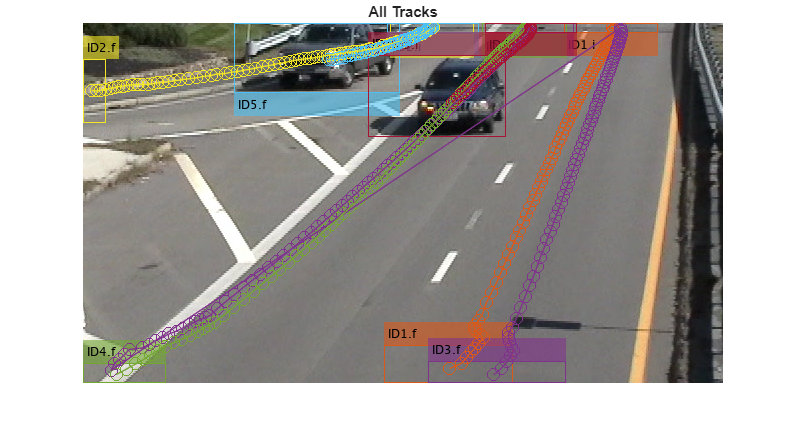

fig = figure;
frame_aux = frame;
frame_aux = plotBboxes(frame_aux, trackssum, -1, display);
frame_aux = plotCentroids(frame_aux, trackssum, -1, display);
imshow(frame_aux);
title('All Tracks');
hold on;
plotTracks(trackssum, -1, display);
hold off;

Si desea visualizar individualmente los track cambie el valor de ID por el del track que desa visualizar

display.video_mode = 0;
IDs = [4];
plotTrackID(frame, trackssum, IDs, display)
T = infoTracks(trackssum, invisibleForTooLong, IDs, display);

T = 1×6 table
    track_IDs    frame_i    ages    totalVisibleCounts    consecutiveInvisibleCount    visibility
    _________    _______    ____    __________________    _________________________    __________

        4          328      116             96                       20                 0.82759  




close all;
clear all; 
clc; 
addpath(genpath(pwd));

% --- SELECCIÓN DEL VÍDEO ---
videofilename = 'atrium.mp4'; 

 % PARÁMETROS DE CONFIGURACIÓN PARA DETECCIÓN
    
    % Área mínima para ser considerada una detección.
    
    MinimumBlobArea = 200; 
    
 % PARÁMETROS DE CONFIGURACIÓN DEL TRACKING
    
    % Coste de no asignar una detección a un track existente.

    costOfNonAssignment = 20; 
 
    % Un track se elimina si:
 
     % a) Es invisible durante un número consecutivo de frames.
     % Mantenemos ~20 frames (aprox 1 seg) para tolerar oclusiones breves 
     % (ej. pasar detrás de otra persona).
     invisibleForTooLong = 90; 
     
     % b) Ratio de visibilidad (visibilidad vs edad).
     % Debe haber sido detectado al menos el 60% del tiempo que lleva vivo.
     visibilityThreshold = 0.5; 
     
     % Edad mínima (frames) para confirmar que es un objeto real y no ruido.
     ageThreshold = 20; 

 % PARÁMETRO DE CONFIGURACIÓN DEL FILTRO DE KALMAN
     
     % 'ConstantVelocity' funciona bien para personas caminando a paso normal.
     MotionModel = 'ConstantVelocity'; 


  % PARÁMETRO PARA VISUALIZACIÓN
    display.speed = 0.0; % Sin retardo artificial
    display.ageThreshold = ageThreshold; 
    display.marker = 'o';
    display.video_mode = 1; % Modo vídeo activado

    display.colors = [0.00 0.45 0.75;
         0.85 0.35 0.10;
         0.95 0.90 0.15;
         0.50 0.20 0.55;
         0.45 0.65 0.20;
         0.30 0.75 0.95;
         0.65 0.075 0.20;
         0.90 0.00 0.45;
         0.35 0.95 0.30;
         0.00 0.25 0.95];

% Inicialización de objetos del sistema
obj = setupSystemObjects(videofilename, MinimumBlobArea);

% Crea una matriz vacía de tracks
[tracks, trackssum]= initializeTracks();

% Contadores
frameId = 1;
nextId = 1;

% BUCLE PRINCIPAL DE PROCESAMIENTO
while hasFrame(obj.reader)
    
    frame = readFrame(obj.reader);
    
    % 1. DETECCIÓN (Background Subtraction)
    mask = obj.detector(frame);

    % --- OPERACIONES MORFOLÓGICAS ---
    % Cruciales en 'atrium' porque la ropa de la gente puede tener colores 
    % similares al suelo, "rompiendo" el blob en trozos.
    se = strel('disk', 4); % Usamos un disco pequeño
    mask = imopen(mask, se);  % Elimina ruido
    mask = imclose(mask, se); % Une partes del cuerpo separadas
    % --------------------------------

    % Realiza un análisis de blobs para encontrar los componentes conectados.
    [detections.area, detections.centroids, detections.bboxes] = obj.blobAnalyser(mask);
  
    % 2. PREDICCIONES (Kalman predice dónde deberían estar las personas)
        tracks = predictNewLocationsOfTracks(tracks);

    % 3. ASIGNACIÓN (Casa predicciones con las nuevas detecciones reales)
        [assignments, unassignedTracks, unassignedDetections] = detectionToTrackAssignment(tracks, detections.centroids, costOfNonAssignment);

    % 4. ACTUALIZACIÓN DE TRACKS
        % Actualiza tracks existentes con datos nuevos
        [tracks, trackssum] = updateAssignedTracks(tracks, trackssum, assignments, detections);
    
        % Gestiona tracks que no encontraron detección (predicción pura)
        [tracks, trackssum] = updateUnassignedTracks(tracks, trackssum, unassignedTracks);
    
    % 5. GESTIÓN DE VIDA DEL TRACK
        % Borra tracks perdidos
        tracks = deleteLostTracks(tracks, invisibleForTooLong, ageThreshold, visibilityThreshold);
    
        % Crea nuevos tracks para detecciones sin dueño
        [tracks, trackssum, nextId] = createNewTracks(tracks, trackssum, detections, unassignedDetections, MotionModel, nextId, frameId);
    
    % 6. VISUALIZACIÓN
      displayTrackingResults(obj, frame, mask, tracks, trackssum, display);
       
    frameId = frameId + 1;

end

% Cierra ventanas
uiscopes.close('All'); 

% --- RESULTADOS FINALES ---
close all
display.ageThreshold = 0; % Mostrar todos, incluso los que duraron poco
display.marker = 'o';
display.video_mode = 0; % Modo estático

% Recopila información
T = infoTracks(trackssum, invisibleForTooLong, -1, display);

T = 11×6 table
    track_IDs    frame_i    ages    totalVisibleCounts    consecutiveInvisibleCount    visibility
    _________    _______    ____    __________________    _________________________    __________

        1           47      344            135                       90                 0.39244  
        2           53      458            280                        0                 0.61135  
        3          163       13              6                        7                 0.46154  
        4          164        5              2                        3                     0.4  
        5          178       19              9                       10                 0.47368  
        6          264      247            187                       30                 0.7570


% Muestra imagen final con todas las trayectorias
fig = figure;
frame_aux = frame;

% pintar cajas y centroides si las funciones auxiliares están disponibles
try
    frame_aux = plotBboxes(frame_aux, trackssum, -1, display);
    frame_aux = plotCentroids(frame_aux, trackssum, -1, display);
catch
    warning('Funciones de ploteo no disponibles en el path');
end

imshow(frame_aux);
title(['Resultados para: ' videofilename]);
hold on;
try
    plotTracks(trackssum, -1, display);
catch
end
hold off;

% Opción para ver un track individual (ejemplo ID 4)
% IDs = [4];
% plotTrackID(frame, trackssum, IDs, display)




% ---------------------------------------------------------
% TEMA 6: MULTIPLE OBJECT TRACKING CON YOLO v4
% ---------------------------------------------------------
clear all; close all; clc; 
addpath(genpath(pwd));

% 1. CONFIGURACIÓN (Video y Red Neuronal)
% ---------------------------------------------------------
videofilename = 'visiontraffic.avi'; % 

% Cargar el detector YOLO
% name = 'csp-darknet53-coco'; % 
name = 'csp-darknet53-coco';     % Usamos este para que no se te cuelgue el PC
detector = yolov4ObjectDetector(name);

% Configurar qué buscamos
if contains(videofilename, 'traffic')
    targetClasses = {'car', 'truck', 'bus'};
else
    targetClasses = {'person'};
end

% 2. PARÁMETROS DEL TRACKER (KALMAN)
% ---------------------------------------------------------
% Estos son los mismos parámetros que ajustaste en el ejercicio anterior
costOfNonAssignment = 40; 
invisibleForTooLong = 20; 
visibilityThreshold = 0.6; 
ageThreshold = 8; 
MotionModel = 'ConstantVelocity'; 

% Inicialización de variables de tracking
[tracks, trackssum] = initializeTracks();
display.speed = 0.0; display.ageThreshold = ageThreshold; display.video_mode = 1;
reader = VideoReader(videofilename);
frameId = 1;
nextId = 1;

% 3. BUCLE PRINCIPAL
% ---------------------------------------------------------
while hasFrame(reader)
    frame = readFrame(reader);

    % --- PASO A: DETECCIÓN (CÓDIGO DEL PROFESOR INTEGRADO) ---
    [bboxes, scores, labels] = detect(detector, frame, 'Threshold', 0.45);

    % --- PASO B: FILTRADO Y MATEMÁTICAS ---
    % Filtramos solo coches o personas
    relevantIdx = ismember(labels, targetClasses);
    bboxes = bboxes(relevantIdx, :);

    % [IMPORTANTE] YOLO da cajas [x,y,w,h]. Kalman necesita PUNTOS [x,y].
    % Hacemos la conversión matemática aquí:
    if ~isempty(bboxes)
        centroidsX = bboxes(:, 1) + bboxes(:, 3) / 2;
        centroidsY = bboxes(:, 2) + bboxes(:, 4) / 2;
        
        % Preparamos la estructura 'detections' para el Tracker
        detections.centroids = [centroidsX, centroidsY];
        detections.bboxes = bboxes;
        detections.area = bboxes(:, 3) .* bboxes(:, 4);
    else
        detections.centroids = [];
        detections.bboxes = [];
        detections.area = [];
    end

    % --- PASO C: TRACKING (LÓGICA KALMAN OBLIGATORIA) ---
    % Todo esto es necesario para mantener los IDs y las trayectorias
    
    tracks = predictNewLocationsOfTracks(tracks); % 1. Predecir

    [assignments, unassignedTracks, unassignedDetections] = ...
        detectionToTrackAssignment(tracks, detections.centroids, costOfNonAssignment); % 2. Asignar

    [tracks, trackssum] = updateAssignedTracks(tracks, trackssum, assignments, detections); % 3. Actualizar
    [tracks, trackssum] = updateUnassignedTracks(tracks, trackssum, unassignedTracks);
    
    tracks = deleteLostTracks(tracks, invisibleForTooLong, ageThreshold, visibilityThreshold); % 4. Limpiar
    
    [tracks, trackssum, nextId] = ...
        createNewTracks(tracks, trackssum, detections, unassignedDetections, MotionModel, nextId, frameId); % 5. Crear nuevos

    % --- PASO D: VISUALIZACIÓN ---
    try
        % Pasamos una máscara vacía porque YOLO no usa fondo
        mask = false(size(frame,1), size(frame,2));
        displayTrackingResults([], frame, mask, tracks, trackssum, display);
    catch
        % Si falla la función del profesor, dibujamos solo las cajas de YOLO
        imshow(insertObjectAnnotation(frame, 'rectangle', bboxes, 'YOLO'));
        drawnow;
    end
       
    frameId = frameId + 1;
end

% 4. RESULTADOS FINALES
uiscopes.close('All'); 
figure; imshow(frame); hold on;
try plotTracks(trackssum, -1, display); end
title('Trayectorias Finales con YOLO');
hold off;

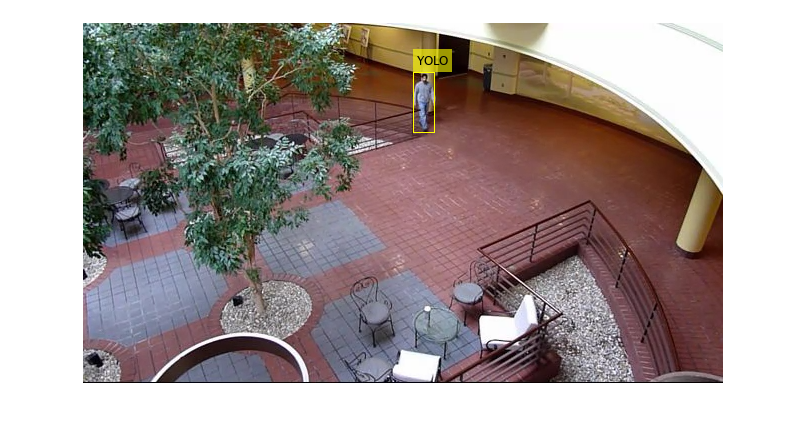


% ---------------------------------------------------------
% TEMA 6: MULTIPLE OBJECT TRACKING CON YOLO v4
% ---------------------------------------------------------
clear all; close all; clc; 
addpath(genpath(pwd));

% 1. CONFIGURACIÓN (Video y Red Neuronal)
% ---------------------------------------------------------
videofilename = 'atrium.mp4'; % 

% Cargar el detector YOLO
% name = 'csp-darknet53-coco'; % 
name = 'csp-darknet53-coco';     
detector = yolov4ObjectDetector(name);

% Configurar qué buscamos
if contains(videofilename, 'traffic')
    targetClasses = {'car', 'truck', 'bus'};
else
    targetClasses = {'person'};
end

% 2. PARÁMETROS DEL TRACKER (KALMAN)
% ---------------------------------------------------------
% Estos son los mismos parámetros que ajustaste en el ejercicio anterior
costOfNonAssignment = 40; 
invisibleForTooLong = 20; 
visibilityThreshold = 0.6; 
ageThreshold = 8; 
MotionModel = 'ConstantVelocity'; 

% Inicialización de variables de tracking
[tracks, trackssum] = initializeTracks();
display.speed = 0.0; display.ageThreshold = ageThreshold; display.video_mode = 1;
reader = VideoReader(videofilename);
frameId = 1;
nextId = 1;

% 3. BUCLE PRINCIPAL
% ---------------------------------------------------------
while hasFrame(reader)
    frame = readFrame(reader);

    % --- PASO A: DETECCIÓN (CÓDIGO INTEGRADO) ---
    [bboxes, scores, labels] = detect(detector, frame, 'Threshold', 0.45);

    % --- PASO B: FILTRADO Y MATEMÁTICAS ---
    % Filtramos solo coches o personas
    relevantIdx = ismember(labels, targetClasses);
    bboxes = bboxes(relevantIdx, :);

    % [IMPORTANTE] YOLO da cajas [x,y,w,h]. Kalman necesita PUNTOS [x,y].
    % Hacemos la conversión matemática aquí:
    if ~isempty(bboxes)
        centroidsX = bboxes(:, 1) + bboxes(:, 3) / 2;
        centroidsY = bboxes(:, 2) + bboxes(:, 4) / 2;
        
        % Preparamos la estructura 'detections' para el Tracker
        detections.centroids = [centroidsX, centroidsY];
        detections.bboxes = bboxes;
        detections.area = bboxes(:, 3) .* bboxes(:, 4);
    else
        detections.centroids = [];
        detections.bboxes = [];
        detections.area = [];
    end

    % --- PASO C: TRACKING (LÓGICA KALMAN OBLIGATORIA) ---
    % Todo esto es necesario para mantener los IDs y las trayectorias
    
    tracks = predictNewLocationsOfTracks(tracks); % 1. Predecir

    [assignments, unassignedTracks, unassignedDetections] = ...
        detectionToTrackAssignment(tracks, detections.centroids, costOfNonAssignment); % 2. Asignar

    [tracks, trackssum] = updateAssignedTracks(tracks, trackssum, assignments, detections); % 3. Actualizar
    [tracks, trackssum] = updateUnassignedTracks(tracks, trackssum, unassignedTracks);
    
    tracks = deleteLostTracks(tracks, invisibleForTooLong, ageThreshold, visibilityThreshold); % 4. Limpiar
    
    [tracks, trackssum, nextId] = ...
        createNewTracks(tracks, trackssum, detections, unassignedDetections, MotionModel, nextId, frameId); % 5. Crear nuevos

    % --- PASO D: VISUALIZACIÓN ---
    try
        % Pasamos una máscara vacía porque YOLO no usa fondo
        mask = false(size(frame,1), size(frame,2));
        displayTrackingResults([], frame, mask, tracks, trackssum, display);
    catch
        % dibujamos solo las cajas de YOLO
        imshow(insertObjectAnnotation(frame, 'rectangle', bboxes, 'YOLO'));
        drawnow;
    end
       
    frameId = frameId + 1;
end